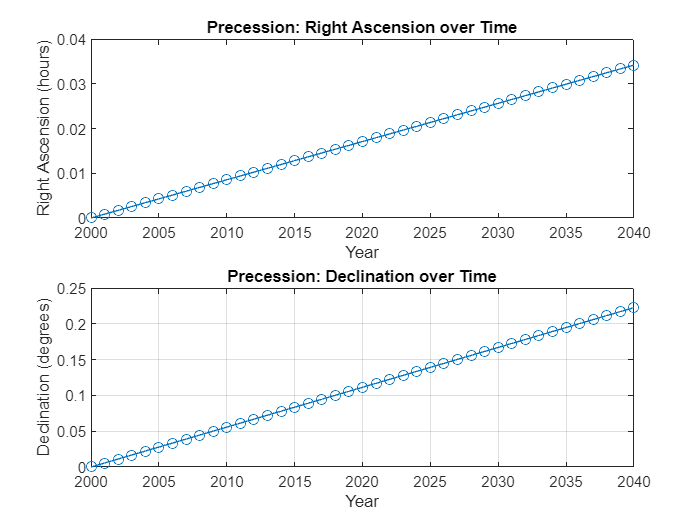

%Precession
start_year = 2000;
end_year = 2040;
mm = 1;           
dd = 1;       
hour = 12;        
minute = 0;
second = 0;
x_init = [1; 0; 0];
years = start_year:end_year;
alpha_results = zeros(1, length(years)); % Right Ascension in hours
delta_results = zeros(1, length(years)); % Declination in degrees

% Loop through each year
for i = 1:length(years)
    yyyy = years(i);
    jd = gre2jd(yyyy, mm, dd, hour, minute, second);
    P = precession(jd);
    x_precessed = P * x_init;
    [phi, lambda, r] = cartesian_to_spherical(x_precessed(1), x_precessed(2), x_precessed(3));
    alpha = lambda / 15;   % Convert to hours (1 hour = 15 degrees)
    delta = phi;           % Declination in degrees
    alpha_results(i) = alpha;
    delta_results(i) = delta;
end

% Plot
subplot(2, 1, 1);
plot(years, alpha_results, '-o');
xlabel('Year');
ylabel('Right Ascension (hours)');
title('Precession: Right Ascension over Time');

subplot(2, 1, 2);
plot(years, delta_results, '-o');
xlabel('Year');
ylabel('Declination (degrees)');
title('Precession: Declination over Time');
grid on;